Sam Kramer

ME 5764: Modelling MEMS/NEMS

Spring 2023

### Midterm II Project

%{
    This MATLAB Live script will be used to complete the midterm II project
    for ME 5764: Modelling MEMS and NEMS in the Spring of 2023. There are 9
    parts that simulate atomic force microscopy systems.

    Sam Kramer
    Due May 5th, 2023
%}

% --Project Setup
    clear; clc; format compact; close all;
    
% --System Parameters
    cant_length = 125*10^-6;        % Cantilever Length (m)
    cant_width = 20*10^-6;          % Cantilever width (m)
    cant_height = 5 * 10^-6;        % Cantilever height (m)
    cant_density = 2300;            % Cantilever density (kg/m^3)
    quality = 300;                  % Quality Factor
    A0 = 20*10^-9;                  % Amplitude of free oscillation (m)
    gamma_sv = 30*10^-3;            % Surface energy (J/m^2)
    H = 6*10^-20;                   % Hamaker Constant (J)
    R = 20*10^-9;                   % Cantilever Tip Radius (m)
    E_t = 130*10^9;                 % Cantilever Elastic Modulus (Pa)
    v_t = 0.3;                      % Cantilever Poisson coefficient
    E_s = 70*10^9;                  % Sample Elastic Modulus (Pa)
    v_s = 0.3;                      % Sample Poisson Coefficient

### Prework: Solving for Parameters from Homework 7

% --Spring Constant K
    I = (1/12) * cant_width * (cant_height^3);      % Area moment of inertia
    K = (3 * E_t * I) / (cant_length^3);
    
% --Natural Frequency in rad/s and Hz
    C = (1.8751 / cant_length)^2;
    w0 = C * sqrt((E_t*I)/(cant_density * cant_width * cant_height));   % rad/s
    f0 = w0 / (2*pi);     % Hz
    
% --Equivalent Mass
    equivalent_mass = K / (w0^2);
    
% --Damping Coefficient gamma
    gamma = sqrt(K * equivalent_mass) / quality;
    
% --Period
    P = 1/f0;
    
% --Drive frequency
    damping_ratio = 1 / (2*quality);
    wd = w0 * sqrt(1 - damping_ratio^2);
    
% --Driving Force 
    term1 = (equivalent_mass^2) * (w0^2 - wd^2);
    term2 = (gamma^2) * (wd^2);
    Fd = A0 * sqrt(term1 + term2);
    
% --Calculating a0
    beta = (1 - E_s/E_t);
    a0 = ((beta*H*R) / (3*K))^(1/3);
    
% --Making a table
    parameters = [K w0 f0 equivalent_mass gamma P wd Fd a0]';
    titles = ["spring constant","natural frequency (rad/s)", "Natural Frequency (Hz)","Equivalent Mass", ...
              "Damping Coefficient", "Period", "Drive Frequency", "Driving Force", "Intermolecular distance"]';
    t = table(titles, parameters);
    disp(t)

              titles               parameters
    ___________________________    __________
    "spring constant"                    41.6
    "natural frequency (rad/s)"    2.4418e+06
    "Natural Frequency (Hz)"       3.8863e+05
    "Equivalent Mass"              6.9769e-12
    "Damping Coefficient"          5.6788e-08
    "Period"                       2.5731e-06
    "Drive Frequency"              2.4418e+06
    "Driving Force"                2.7733e-09
    "Intermolecular distance"      1.6433e-10


    
% --Calculating the forces to the system and plotting them
    d = a0:(1*10^-11):(6*10^-10);
    F_Vanderwaal = -H*R ./ (6.*d.^2);
    figure
    plot(d, F_Vanderwaal)
    xline(a0);
        hold on
        grid on
    
% --Calculating adhesion and repulsion forces
    ts = 1*10^-12;
    d = 0:ts:a0 + ts;
    E_star = (((1 - v_t^2)/E_t) + ((1 - v_s^2)/E_s));
    F_DMT = (-4*pi*R*gamma_sv) + ((4*sqrt(R)) / (3*E_star)) .* ( (a0 - d).^(3/2) ) ;
    plot(d, F_DMT)

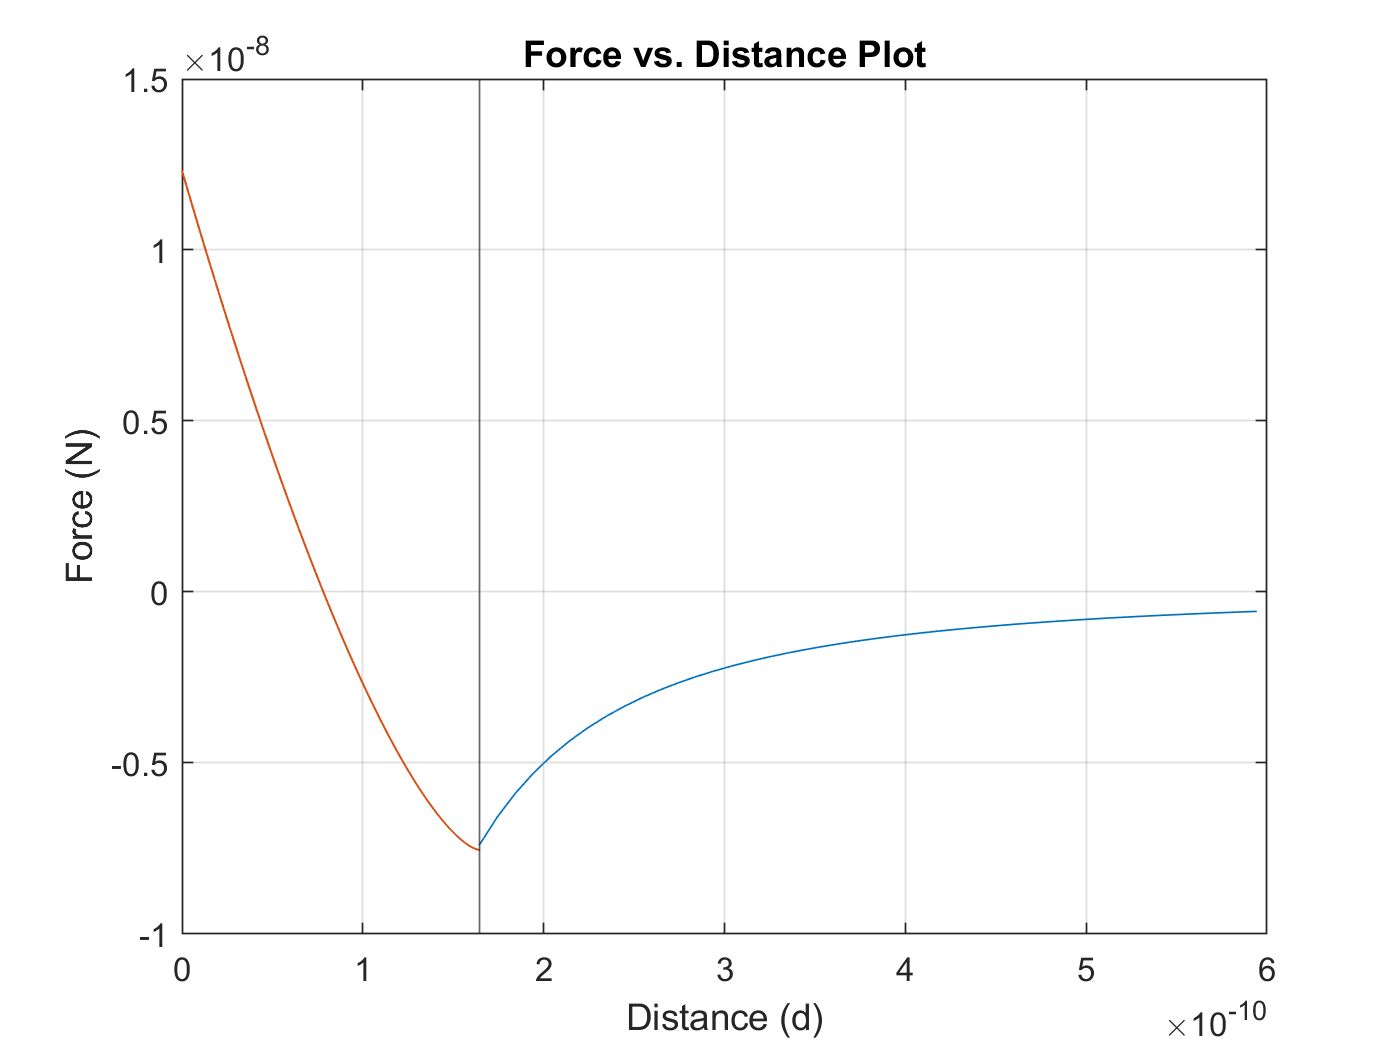

        hold on
        xlabel('Distance (d)')
        ylabel('Force (N)')
        title('Force vs. Distance Plot')

        
% --Calculating mass
    mass = cant_width * cant_height * cant_length * cant_density;

## Part 1: Simple Driven Oscillator

- This section of the code will be responsible for solving for a damped-driven harmonic oscillator with the absensce of any tip-surface forces. The equations thats that will be solved are defined as

#### 
$$m\ddot{z} +\gamma \dot{z} +\textrm{kz}=F_d$$


    If we were to convert this system into two first order equations we would return system of equations that looks like this below:

#### 
$$\textrm{AFM}\;\textrm{model}=\left\lbrace \begin{array}{ll}
v=\dot{z}  & \\
\dot{v} =\frac{1}{m}F_d -\frac{\gamma }{m}v-{w_0 }^2 z & 
\end{array}\right.$$


    In this equation v is the velocity and z is the position of the system, m is the equivalent mass, and gamma is the damping coefficient. This part of the project will be used to debug the code for finding our ODE solutions. 

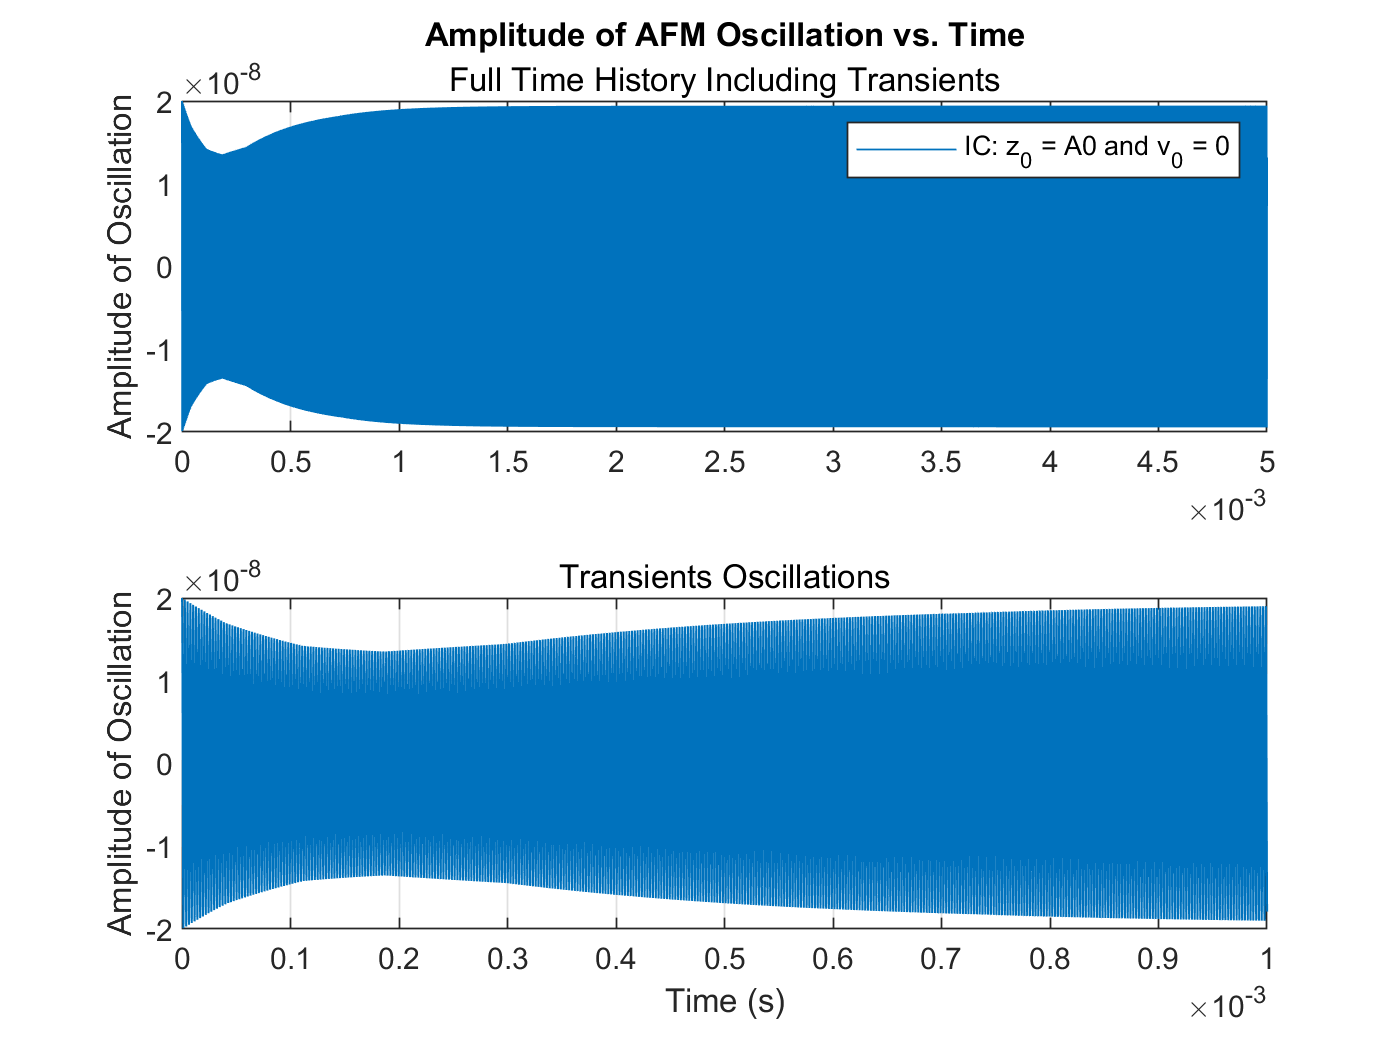

% --Setup

    % --Initial conditions
        z0 = A0;
        v0 = 0;
        initials = [z0; v0];
    
    % --Time steps
        dt = P/20;                          % Time step
        time_span = 0:dt:.005;              % Time vector
    
% --Function declaration
    system = @(t,zv) [zv(2);
                         (Fd/equivalent_mass) * cos(wd*t) - (gamma/equivalent_mass) * zv(2) - (K/equivalent_mass) * zv(1)];

% --Solve for system using ode45 function [CHANGE LATER?] 
    [t,zv] = ode45(system, time_span, initials);
    z = zv(:,1);
    v = zv(:,2);
    
% --Plot Amplitude
    figure(1)
    subplot(2,1,1)      % Full time history
    plot(t,z)
        ylabel('Amplitude of Oscillation')
        title('Amplitude of AFM Oscillation vs. Time')
            subtitle('Full Time History Including Transients')
        grid on
        hold on
        legend('IC: z_0 = A0 and v_0 = 0')
            
    subplot(2,1,2)      % Transient subplot
    plot(t,z)
        xlim([0.00 0.001])
        xlabel('Time (s)')
        ylabel('Amplitude of Oscillation')
            subtitle('Transients Oscillations')
        grid on

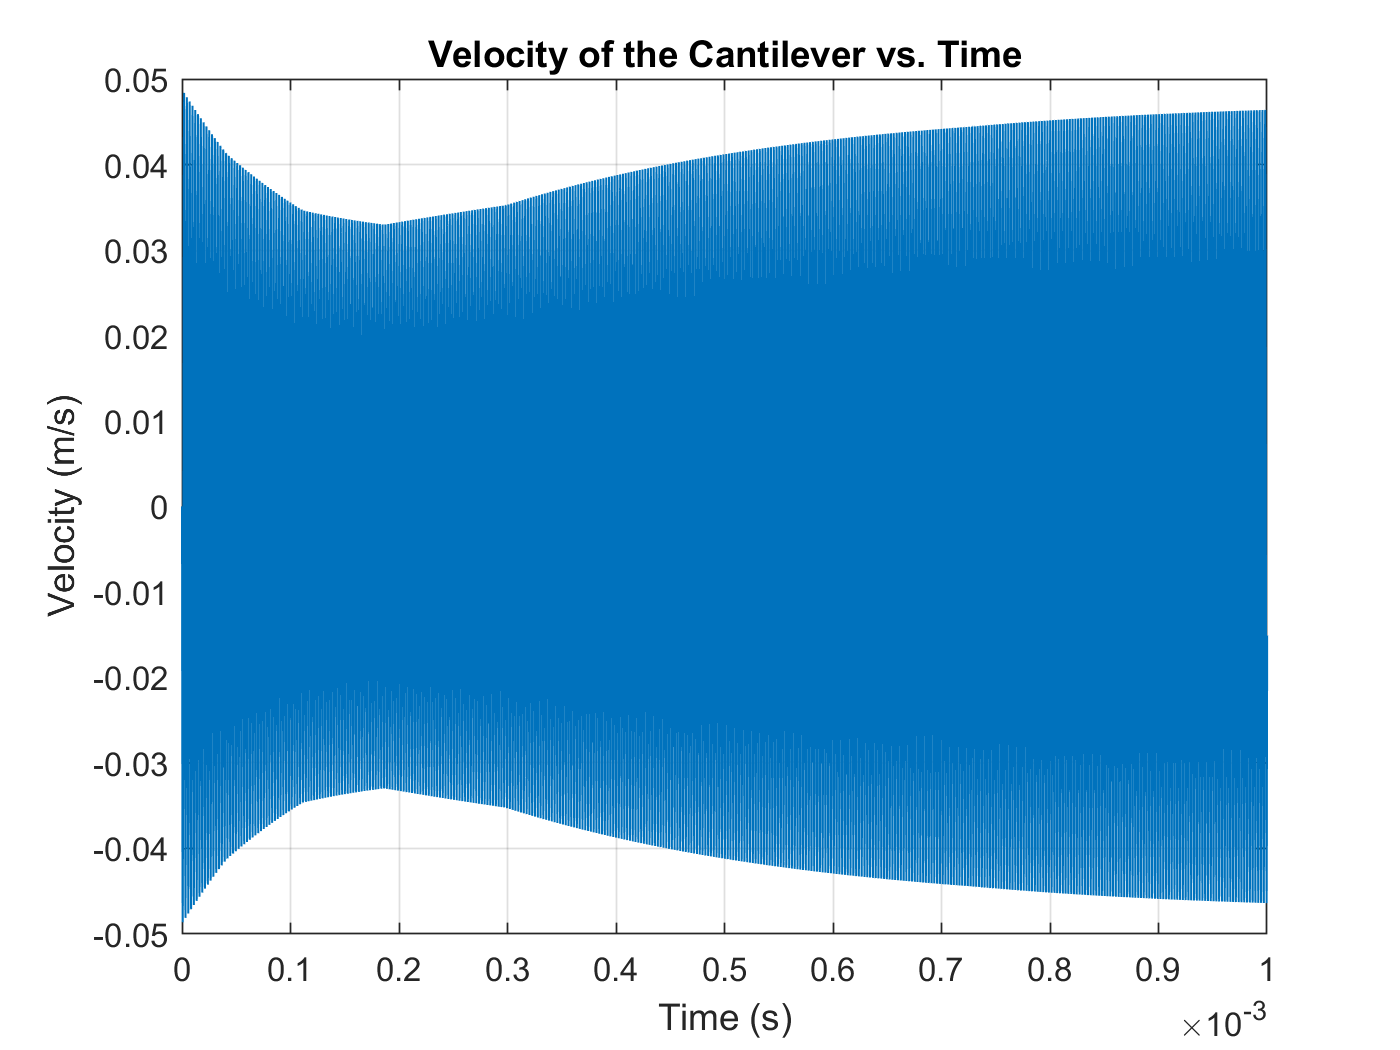

        
% --Velocity Graph
    figure(2)
    plot(t,v)
        xlim([0 0.001])
        grid on
        hold on
        xlabel('Time (s)')
        ylabel('Velocity (m/s)')
        title('Velocity of the Cantilever vs. Time')

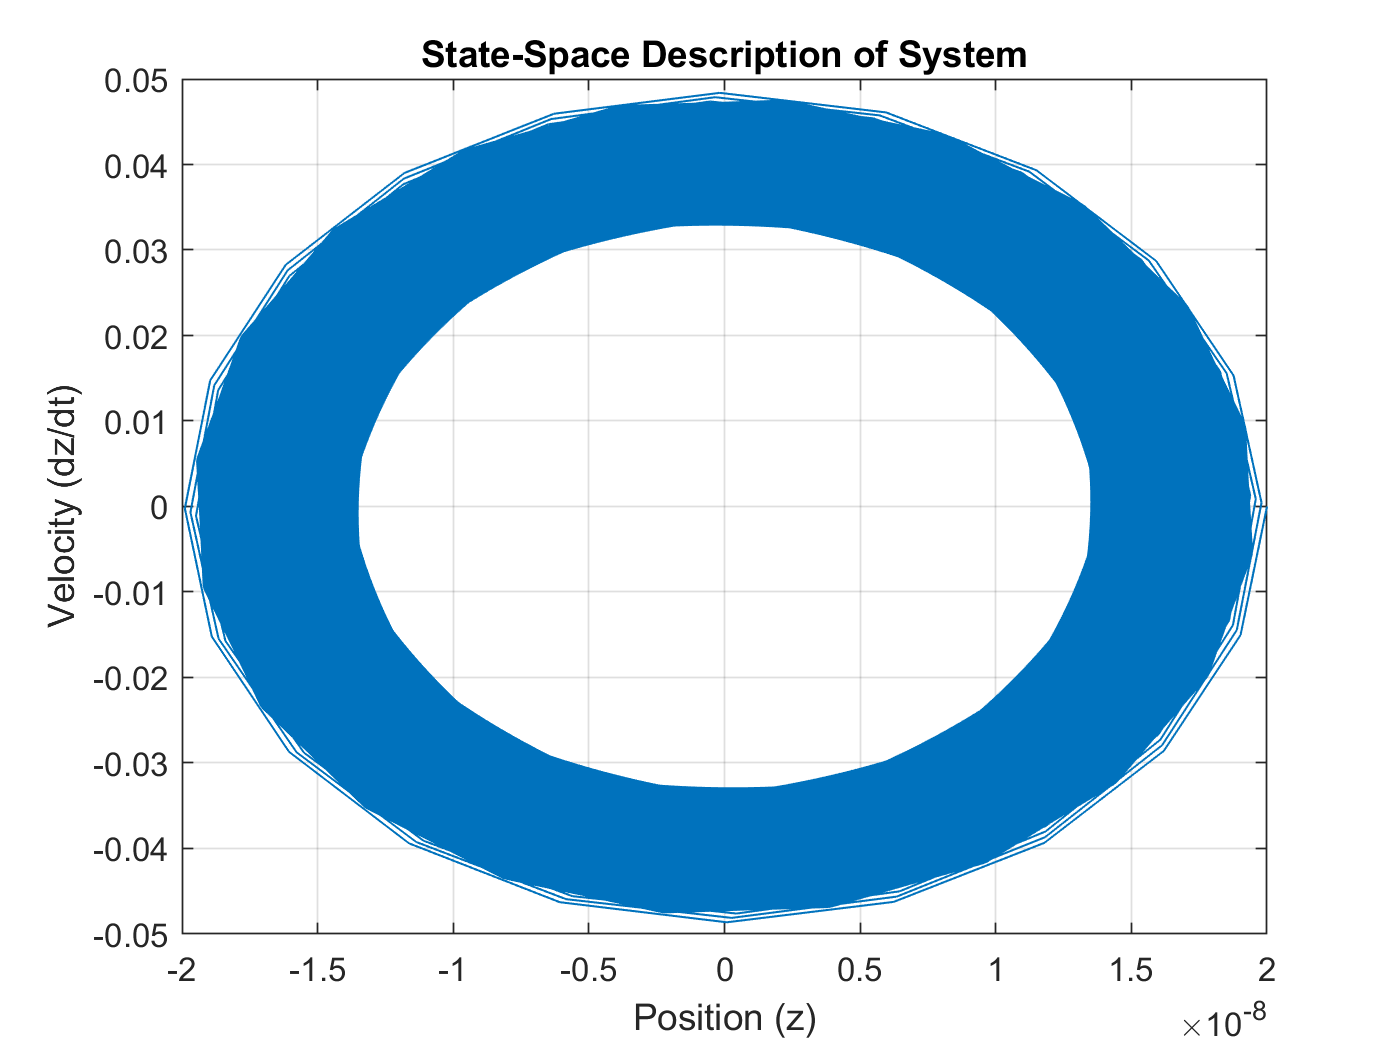

        
% --State Space description
    figure(3)
    plot(z,v)
        grid on
        xlabel('Position (z)')
        ylabel('Velocity (dz/dt)')
        title('State-Space Description of System')

## Part 2: Analysis of Part 1 Solution

    2. Provide some plots that show convincing evidence that your code is correct for problem 1. Choose some quantity of interest and compare the results of your code with the exact analytical solution. The choice of plots and comparison is up to you. The intention of this part is to validate your code where we have an analytical solution to compare with. 

    For this part of the solution there were a few things that I focused on. I first plotted the solution that was derived from the ODE solver that I selected. I plotted the transients and the entire time history as well as the velocity of the cantilever tip vs. time. I also selected to include a state-space description of the oscillation. Lastly, I used my own code to calculate a discrete fourier transform of the system. This will be used to verify the resonant frequencies. 

% --Formatting DFT
    T = max(time_span);                           % Signal Period
    
% --Finding the DFT of the signal
    [frequency, amplitude, phase] = fourier(z',T);
    
% --Plotting DFT
    figure(4)
    subplot(2,1,1)
    plot(frequency, amplitude)
        xlim([0 6*10^5])
        grid on
        hold on
        ylabel('Amplitude (m)')
        title('Discrete Fourier Analysis of AFM Vibration')
        subtitle('Amplitude')
        
    subplot(2,1,2)
    plot(frequency, phase)

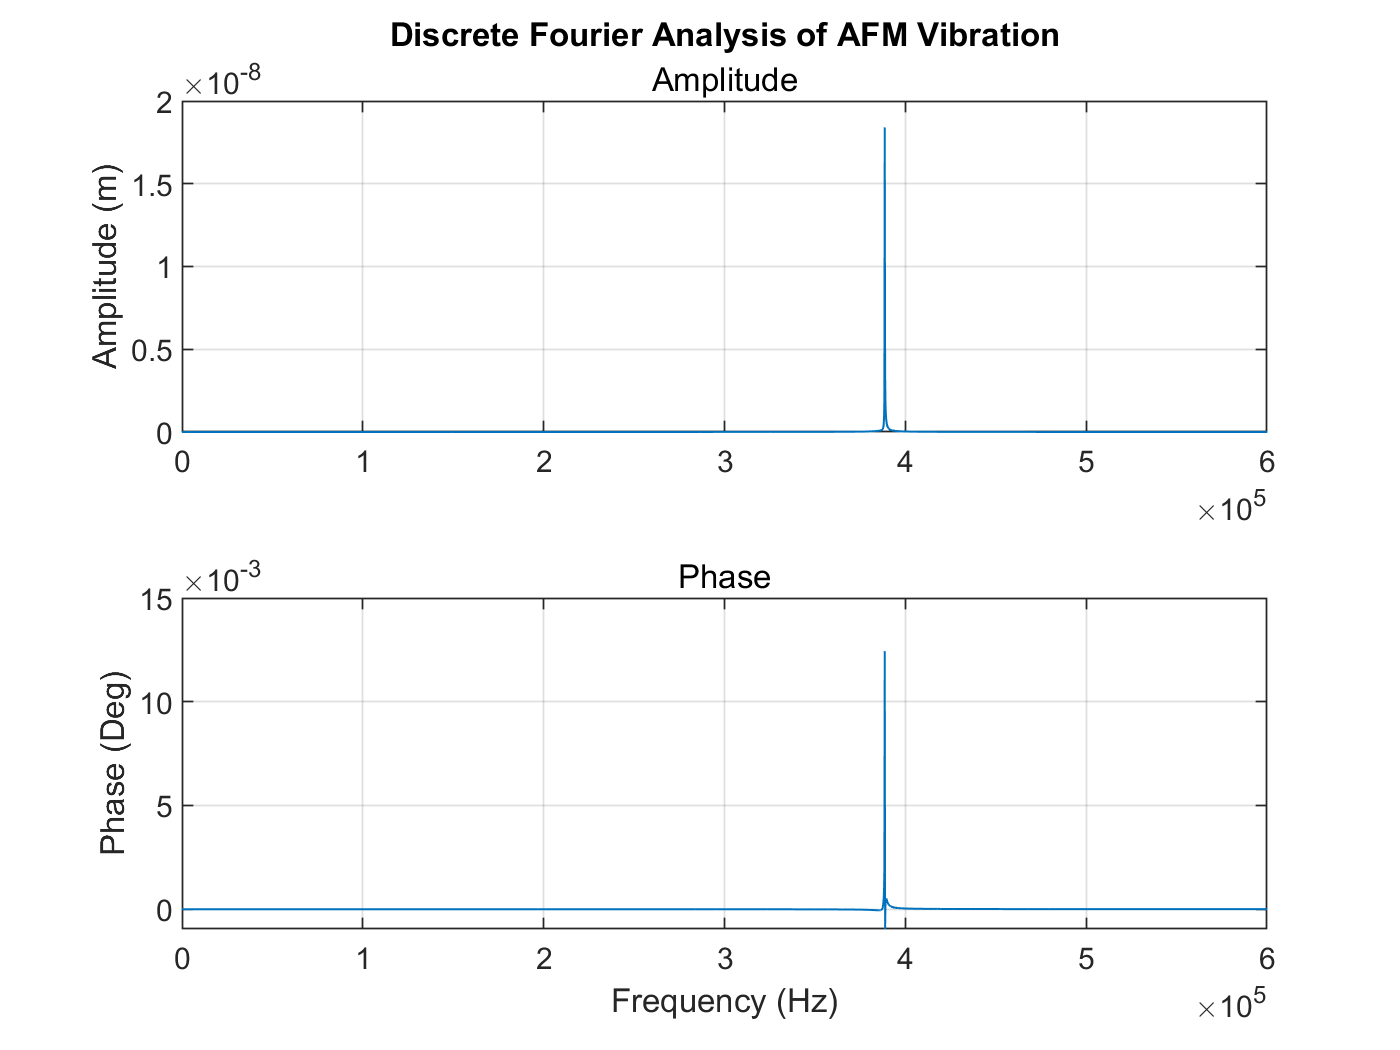

        xlim([0 6*10^5])
        xlabel('Frequency (Hz)')
        ylabel('Phase (Deg)')
        subtitle('Phase')
        grid on
        hold on

## Part 3: Discussion of code

    To validate that the first simulation of my code is correct I first wanted to speak about the transient dynamics of the oscillation that occur. The initial decay of the system as it begins to oscillate is symbolic of a system with damping that begins with an inital displacement. For our system I chose an initial displacement of A0 and that is precisely what is shown on the graph. These transients follow a logarithmic decay, which is exactly from what we would expect our system to exhibit when underdamped. We know our system is underdamped because we have a high quality factor. This is useful for maintaining the oscillations of the AFM cantilever. The logarithmic decay is slow relative to the number of oscillations that are observed, which is expected from an system with a high quality factor. 

    After the transients, there the forcing of the equation overcomes the damping force and begins to accelerate the cantilever. The forcing doesn't initially occur when the system begins because of the inertia of the cantilever at the microsecond timescale needs to be accounted for. The amplitude of the oscillations will increase as the forcing of the cantilever overcomes the damping of the cantilever. The oscillations then increase out to a constant value of 1.96x10^-8 meters. This value continues to grow, albeit slowly. This does not grow back to the full amplitude, which could come from a variety of reasons, including the numerics of the ODE45 solver and the size of the time step. 

    Looking at our state-space description, the circular pattern that is created is expected of the system because our AFM system does not settle and the oscillations continue. This would appear as a circle in the phase-portrait or state-space description of the AFM. There would be red flags if the state-space portrait were to land on a signle fixed point or were to oscillate in another pattern. The width of the circle also aligns with the expected amplitude of the oscillations of the AFM. The thickness of the state-space circle is due to the transient oscillations that decay and then grow back to the stable amplitude. 

    Using a fourier transform we are able to estimate the mode shape of the system. Regarding the amplitude plot, we can see that the peak occurs at 388,610 Hz, which is where we would expect the peak to be because that is frequency that we decided to drive the system at. There is some degree of error because of the time step that was selected, and there is a frequency resolution of 200Hz. Because there is zero phase, the amplitude is scaled to be an estimate of the mean of the amplitude of the oscillations, which we expect to be below 2*10^-8 because of the transients. We expect the shape of the peak to be quite narrow because of the low damping and high quality of the system which we do see. The quality is proportional to the width of the spike at a -3dB drop from the peak. The fourier analysis is limited because of the small time step needed for a small frequency resolution, however this is computational expensive to calculate a DFT with such a small time step. I chose to take a long period sample in order to eliminate any potential for aliasing within the DFT amplitude, that is why the solution plot is extended out to .005 seconds.

## Part 4: Simulating with VDW Forces

    4. Solve for the dynamics of the cantilever including only the van der Waals contribution to the tip-surface interation force. Solve for the dynamics of the cantilever for the following z separations. z*c = 1, 1.1, 1.2, 1.3, 1.4, 1.5, 1.6.  For each simulation, use an initial condition of z*(0) = 1 and z*'(0) = 0 and let the mass reach a steady oscillating state.

% --Problem Setup

    % --Parameters
        zc_star = [1.0 1.1 1.2 1.3 1.4 1.5 1.6];
        z_solution = [];
        v_solution = [];
        t_solution = [];
        
    % --VDW Forces Parameter
        m = equivalent_mass;
        lambda = (1/(m*A0*w0^2));
        VDW_constant = (H*R/6);

    % --Initial conditions
        z0_star = 1;
        v0_star = 0;
        initials = [z0_star; v0_star];
        
    % --Time parameters
        t_end = 0;
        t_final = 5000;
        time_span = t_end:.01:t_final;              % Time vector
    
% --Finding Solutions
    for i = 1:length(zc_star)
        
        % --Function declaration
            system = @(t,zv) [zv(2);
                              lambda * Fd * cos((wd/w0)*t) ...                                  % Drive Forces
                              - lambda * VDW_constant * (1/((zv(1)*A0 + zc_star(i)).^2)) ...    % VDW Forces
                              - ((1/quality)*zv(2)) - (zv(1))];                                 % System Dynamics
           
        % --Solve for system using ode45 function 
            [t,zv] = ode45(system, time_span, initials);
            z = abs(zv(:,1));
            v = zv(:,2);
            
        % --Store values
            z_solution = [z_solution z];
            v_solution = [v_solution v];
            t_solution = [t_solution t];
            
    end

4a. Plot z* versus z*c where z* is the amplitude of the oscillation and z*(t*) when the mass is oscillating steadily and z*c = zc/A0. 

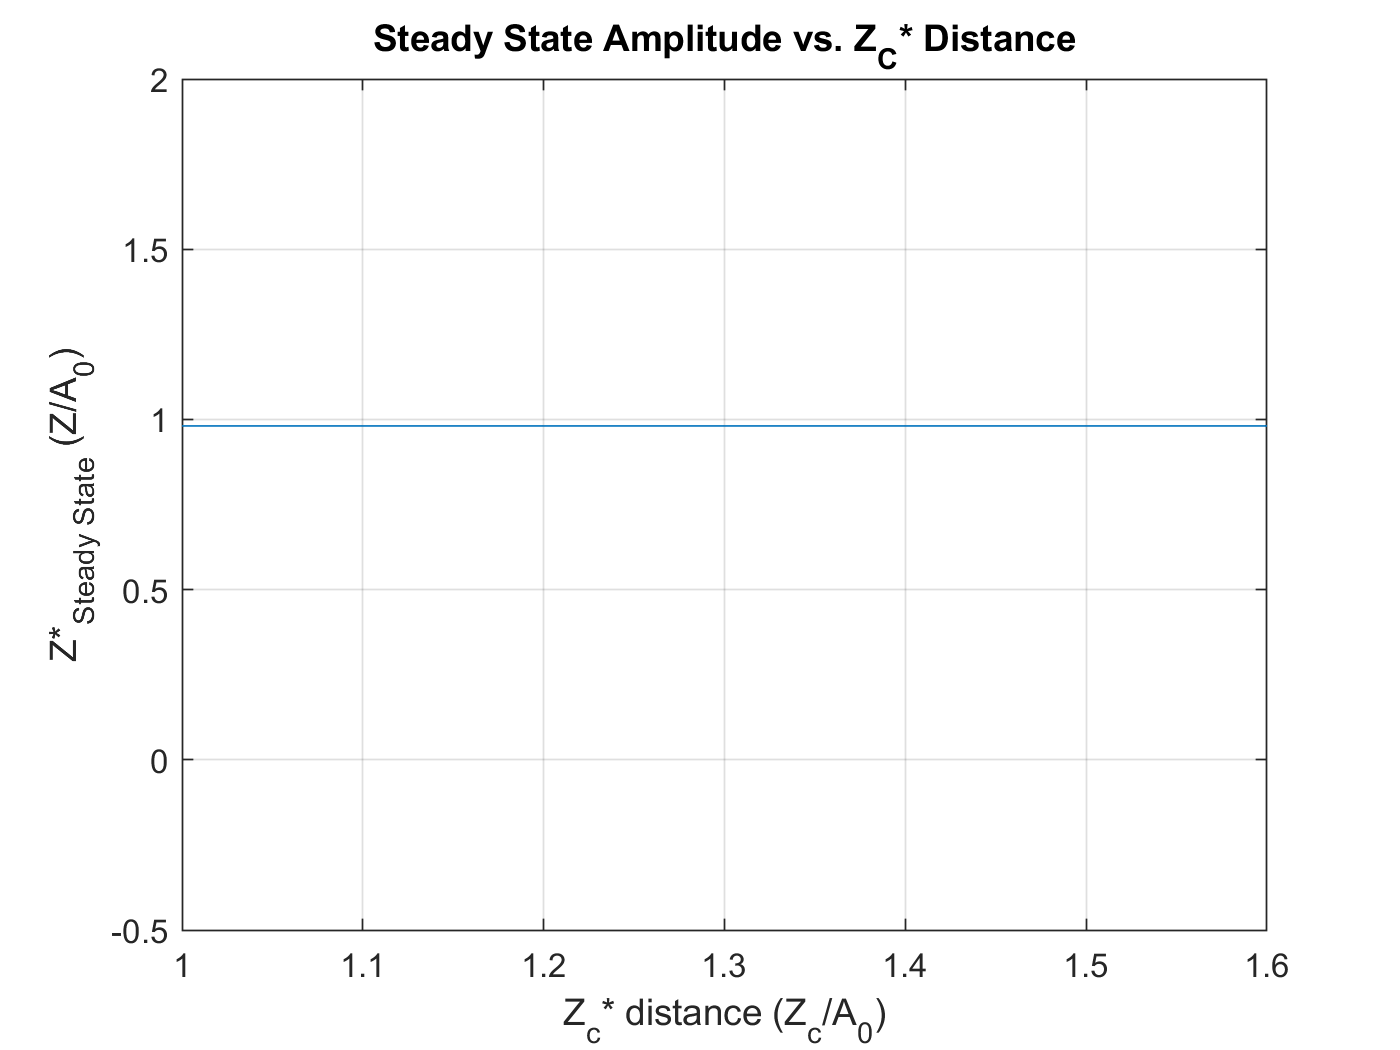

% --Setup
    peak_solution = [];
    
% --For loop
    for n = 1:width(z_solution)
        
        % --Finding the peak
            [peak, ind] = findpeaks(z_solution(:,n));
            
        % --Finding the peak value
            peak_val = peak(length(ind));
            
        % --Storing value   
            peak_solution = [peak_solution peak_val];
        
    end
    
% --Plotting solutions vs. Zc location
    figure(6)
    plot(zc_star, peak_solution)
        hold on
        grid on
        title('Steady State Amplitude vs. Z_C* Distance')
        xlabel('Z_c* distance (Z_c/A_0)')
        ylabel('Z*_{Steady State} (Z/A_0)')
        xlim([1 1.6])

4b.  

    To me this plot makes physical sense, and the reason is two-fold. The first reason is because at a distance when Zc = A0, the Van Der Waals forces are so small they are mostly insignificant for the majority of the oscillation period. This would not have much of an effect on the oscillation of our cantilever as the dominant forces would be the drive force, and as a result the peak amplitude would remain the same as when there were no Van Der Waals forces. As the separation distance increased, the line would theoretically remain the same because there should be no changing effect as the distance gets larger. As we pull the cantilever away from the surface, the Van Der Waals forces would get smaller, and have even less of an impact on amplitude of the oscillation, therefore causing the amplitude of the oscillation to remain the same.

    Another reason why I believe that this outcome is correct is because of the upper-lower impact graph that we plotted in class to describe the tip-surface forces. In that plot, the non-dimensional amplitude leveled off to a value of 1 at the non-dimensional cantilever base distance. My plots shown that I derived via numerical simulations fit into that narrative of the graph of the theoretical system with tip-surface forces included. That is, they exhibit the same constant linear trend once the cantilever base height reaches a value of A0. 

4c. Plot z'*(t*) versus z*(t*) (Phase-Portrait) for each separation distance on one plot.

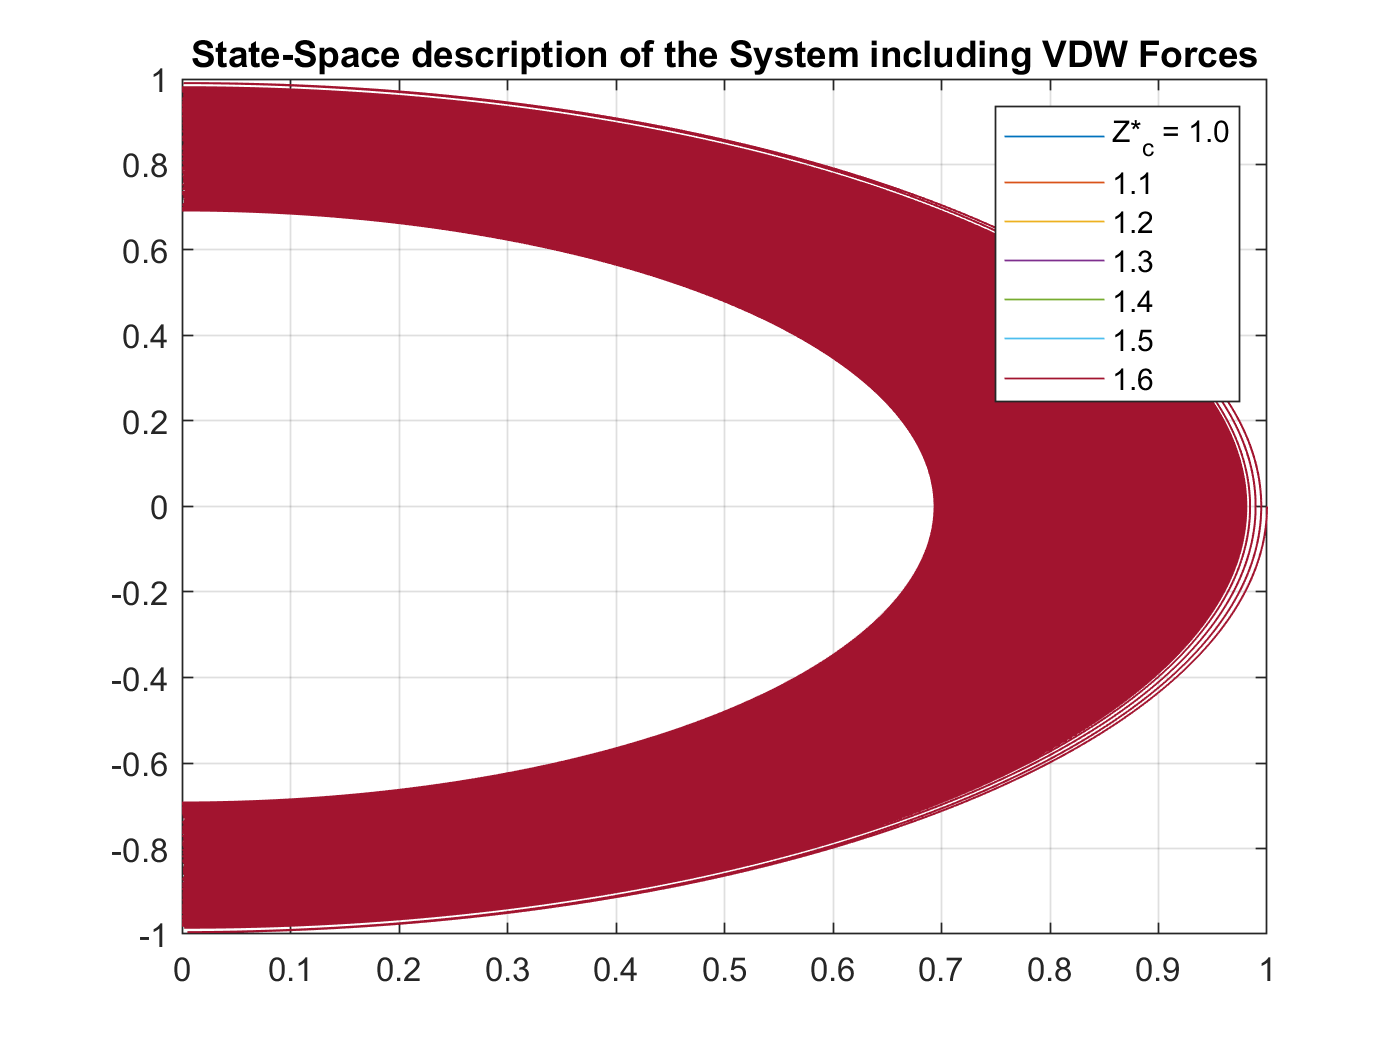

% --plot
    figure(7)
    plot(z_solution,v_solution)
        hold on
        grid on
        title('State-Space description of the System including VDW Forces')
        legend('Z*_c = 1.0','1.1','1.2','1.3','1.4','1.5','1.6')

 4d.

    In terms of the general shape that is plotted, the circular system is what I would expect to appear in the AFM cantilever system. That is because once the driving force is applied the amplitude should remain constant and so it will land on a fixed trajectory within the state space. This also makes sense to me because we have reached steady state oscillations and that is the shape that a forced-damped harmonic oscillator takes at steady state, which we saw in parts 1 and 2. So the circular shape makes sense.

    However, I did not expect them to all appear the exact same. All 7 of the state-space graphs that were plotted remained the same when we varied the normalized cantilever base distance. I did not expect this to occur because I expected the system velocity to change and vary with Z*c, especially when Z*c = 1. At this point I expected there to be a larger negative velocity because of the negative force on the tip due to van der Waals forces. Because of this added negative velocity, I expected the bottom of the circile to be elongated in the y-direction. I expected this elongation to get smaller as Z*c got larger, and eventually our forced-damped system from part 1 would emerge. This however is not the case and all state space plots are the same. 

## Part 5: Full AFM Modeling

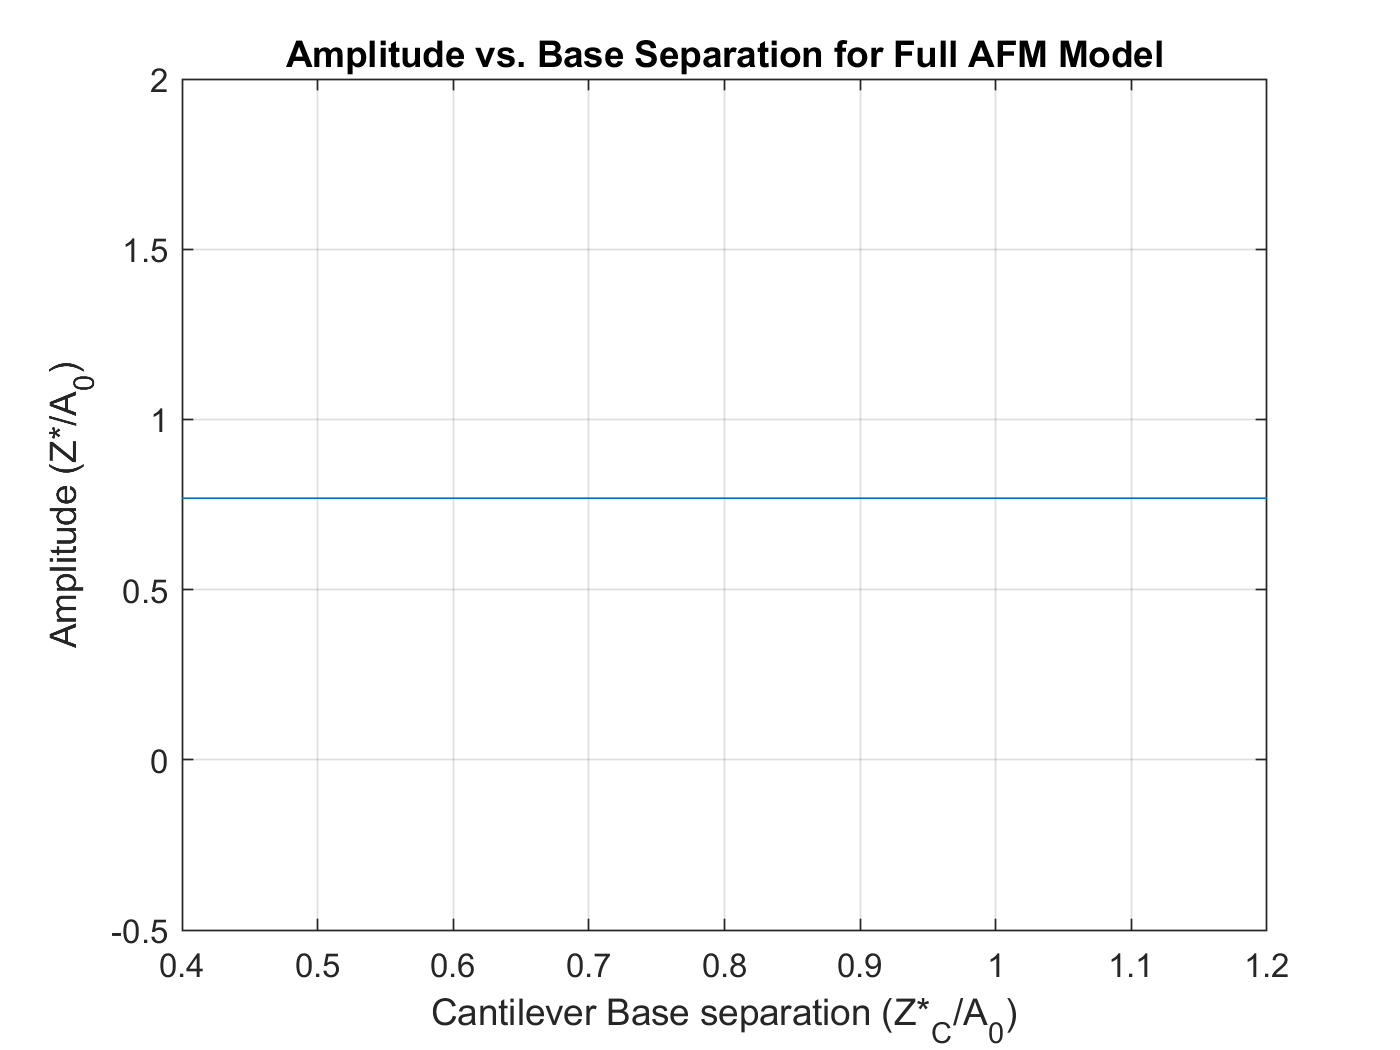

% --Probelm Setup
    
    % --Setup Parameters
        zc_star = [0.4 0.6 0.8 1.0 1.2];  
        solution = [];

    % --Setup Time
        t_end = 0;
        t_final = 4000;
        time_span = t_end:.01:t_final;              % Time vector
        
% --Setup the event handling for system
    options = odeset('Events', @intermolecular_distance);               % Event Detection 
    
% --For loop to loop through each Zc condition
    for i = 1:length(zc_star)
        
        % --For loop Setup
            initials = [z0_star, v0_star];
            z_solution = [z0_star];
            v_solution = [v0_star];
        
        % --While loop
            while t_end < t_final
                
                % --Define System
                    if (zc_star(i) - z_solution(end)) > a0
                        
                        % --VDW Forces only
                        system = @(t,zv) [zv(2);
                                          lambda * Fd * cos((wd/w0)*t) ...                                  % Drive Forces
                                          - lambda * VDW_constant ...
                                          * (1/((zv(1)*A0 + zc_star(i)).^2)) ...                            % VDW Forces
                                          - ((1/quality)*zv(2)) - (zv(1))];                                 % System Dynamics
                    
                    elseif (zc_star(i) - z_solution(end)) <= a0
                        
                        % --Full System
                        system = @(t,zv) [zv(2);
                                          lambda * Fd * cos((wd/w0)*t) ...                                  % Drive Forces
                                          - ((1/quality)*zv(2)) - (zv(1)) ...                               % System Dynamics
                                          - (H*R)/(6*a0^2) ...                                              % DMT forces 
                                          + (4*E_star/3)*(sqrt(R)/(1-v_s^2)) ...
                                          *(a0 - zv(1)*A0 - zc_star(i))^(3/2)];        
                        
                    end
                
                % --Solve System
                    if length(time_span) >= 2   % Check protection
                        
                        % --Calculate the solutions
                            [t, zv] = ode23s(system, time_span, initials);
                        
                        % --Reformat solutions
                            z = real(zv(:,1));
                            v = real(zv(:,2));
                            
                        % --Save z data
                            z_solution = [z_solution; z];
                            v_solution = [v_solution; v];
                            
                        % --Reformat next time step
                            t_end = t(end);
                            initials = [z(end), v(end)];
                        
                    else
                        
                        % --Break if complete with simulation
                            break                  
                        
                    end 
                    
            end
            
            % --Find Peaks
                z_abs = abs(z);
                [pks, int] = findpeaks(z_abs(end - 1000:end));
                mean_peaks = mean(pks);
                
            % --Store peaks
                solution = [solution, mean_peaks];
                
            % --Plot State Space
                figure(9)
                plot(z_solution,v_solution);
                    hold on
                    grid on
                    xlabel('Cantilever Position (z*)')
                    ylabel("Cantilever Velocity (v*)")
                    title('State Space Description of Full AFM model')
                
    end 
 
% --Plotting Zc vs Z
    figure(8)
    plot(zc_star, solution)
        hold on 
        grid on
        xlabel('Cantilever Base separation (Z*_C/A_0)')
        ylabel('Amplitude (Z*/A_0)')
        title('Amplitude vs. Base Separation for Full AFM Model')

5b. 

    The plot above depicts the maximum steady state oscillations of the cantilever as a function of the cantilever base separation Z*c. The trend that is shown on the graph is a linear trend with zero slop as we get closer and close to zero. This does not make physical sense. While it does make sense that the amplitude of z* should be smaller than the previous part with just the VDW forces, there should be a clear linear trend in the data that decreases as the Z*c also decreases, which my graph does not show at all. Within that trend there should also be two different branches between the high and low routes. This is also not shown in the graph above. This leads me to assume that there is an error within the simulation that is causing these problems. Another difference I notice is that when we go up to 1.2 there should be an amplitude of 1. This is because there should be almost no effects on the tip of the cantilever due to adhesion forces. This would allow our lines to match up with the previous similar graph, but they don't. 

    I suspect that there is some error associated with the switching events of the ODE that is being solved. This could introduce the issues where the amplitude doesn't change when varying Z*c, the value of the adhesion forces are very small during this simulation and as a result it affects the results. This could come from some sort of issue with the event detection function that I used, or the time step could be too small the peaks are being missed for the larger values. 

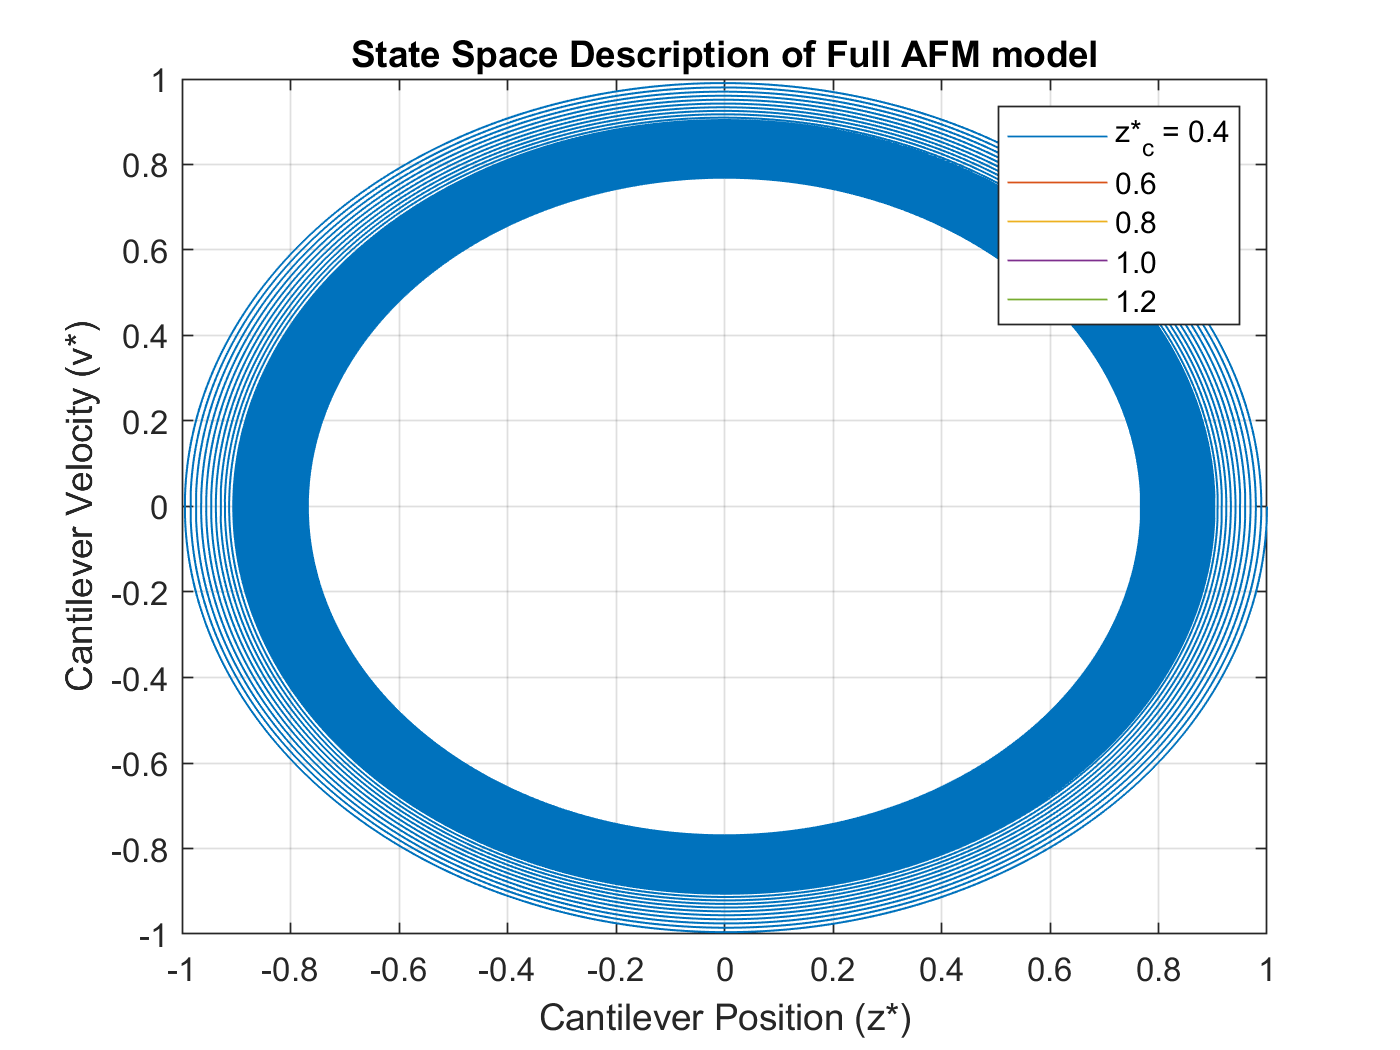

% --Figure 9 Shape Up
    figure(9)
    legend('z*_c = 0.4','0.6','0.8','1.0','1.2')

5d.

    In the plot that shows the state-space representation of the full AFM model. This was not what I expected, but it is not correct. I expected their to be some sort of non-symmetric shape, particularly as we got closer to the test subject. However this is not what we see, the entire system is circular, much like the previous two. It is also concerning that the model goes past the actual theoretical boundaries. If we have the test sample at 0.4 distance away, then theoretically the AFM should not be able to go past that value and would be stopped due to repulsion forces dominating the DMT forces. This mean that at a certain point we could not go past -0.4 on the cantilever position side, and yet we still do. This is concerning and shows an error within the model. It also doesn't make sense that all the same separations would remain the exact same shape. This wouldn't make sense because there should be some sort of variation in the velocity because some of the Z*c values would contact the tetst subject earlier, leading to more time under a dominant force, causing a higher velocity. This would vary the shape of the circle, at least in the y-direction. We do not see this, pointing to an error within the simulation, particularly the replusion forces and point at which the cantilever is deflected away. 

## Part 6: Discussion of Differences

    In the past two parts I noticed that there isn't too much difference in the plots that I coded. The only difference that I noticed is the amplitudes of the steady state oscillations. For the full AFM system there was a steady state amplitude of about 0.76 where as the steady state amplitude for just the VDW forces was at about 0.81. There isn't much of a difference in these amplitudes. However, the amplitudes for the full AFM model are not correct as the simulation is encountering numerical errors. A difference that I noticed in the full AFM model is that there iss a bulge during the transient sections. This bulge has roughly the same amplitude as the VDW forces steady state amplitudes. In terms of the phase portrait of the system, there is still the same circular motion in both, however, the stable paths that the systems fall on have different radii. This is due to the fact that the amplitudes of the two simulations are different. In terms of the normalized plots depicting the amplitude vs. the normalized cantilever position they are both straight lines. However, the full AFM model should not appear this way, instead it should be sloped with a positive slope. The just VDW forces plot appears as it should with the single straight line at the value of 1, which makes sense. 

## Part 7: Discussion of Improvements

    There are numerous improvements that I could make in order to increase the accuracy of the simulations. The first change I would make would be to the simulation would be to make sure that the event detection algorithm works properly. I believe that one issue that I am getting is that my time step is too large and as a result I overshoot the position and therefore I get an numerical error in the simulation. This can be seen by the fact that my amplitude is much larger than the separation of the cantilever and the test sample, the separation was 0.4, yet the amplitude was 0.7, which meant that the cantilever was going through the material which is incorrect. This could have been resolved by making the time step smaller and selectively making it so that it would not overshoot the intermolecular distance. The event detection could avoid this issue, however, I wasn't able to get it working properly for our problem. 

    Another improvement that could be made would be the simplification of my code, I think that I may have made some of the code far too complex. The full AFM model had a series of nested loops and if-conditions that were about 100 lines long and as a result it was difficult for me to catch bugs and errors in my code. I think the syntax and the way that I was storing and tripping the conditions to switch equations was incorrect and contributed to the issues I was having with the event detection algorithms. This could have also allowed me to catch the error that I made that caused my code to be unstable as I reduced the time-step. 

## Part 8: Interesting Insights in this Problem

    There were a few things that I found interesting with this problem. One of the more interesting and fun things that I found with this project was the coding aspect of the problem. I think that it introduced me to interesting tools that could be used in the future. Particularly the switching events with the ODEs. I had not had to use an event detection algorithm before this problem, so learning what that was and attempting to implement it was a new challenge that I enjoyed. In order to fully understand the algorithm I was able to reproduce the ballode() function in matlab on my own. This, in conjunction with the piece-wise ODE equations was an interesting problem that I learned to code for this specific problem. 

    One thing that I had not realized was what the type of plots that non-dimensionalized equations yield. Previously, we had simply solved the equations and not plotted the actual numerical results. This project gave me an appreciation for what they look like. I understood that when we non-dimensionalize we remove the units, however I did not realize that it would essentially make the peak amplitude equal to 1. That can be seen in the graph below. 

    I also did not realize how quick these AFM oscillations would be vibrating. If we look at the figures from figure 1 which are dimensional, the oscillation periods occur on the order of micro-seconds. In fact if we zoom the x-axis out to be about 1 millisecond, then the oscillations are happening so fast, the oscillations on the graph appear to disappear and the graph looks like a single body where the individual oscillations are not visible. 

   I also thought it was interesting how during the transient phases, there is a decrease in the amplitude before the driving force can dominate and bring the amplitude back up to a non-dimensional value of 1. This suggests to me that there is inertia still present with the cantilever, which due to its size, I did not consider would be visible in the oscillations. However, becuause the time scales are so small I believe that it makes sense that in the first few microseconds inertia would be present.

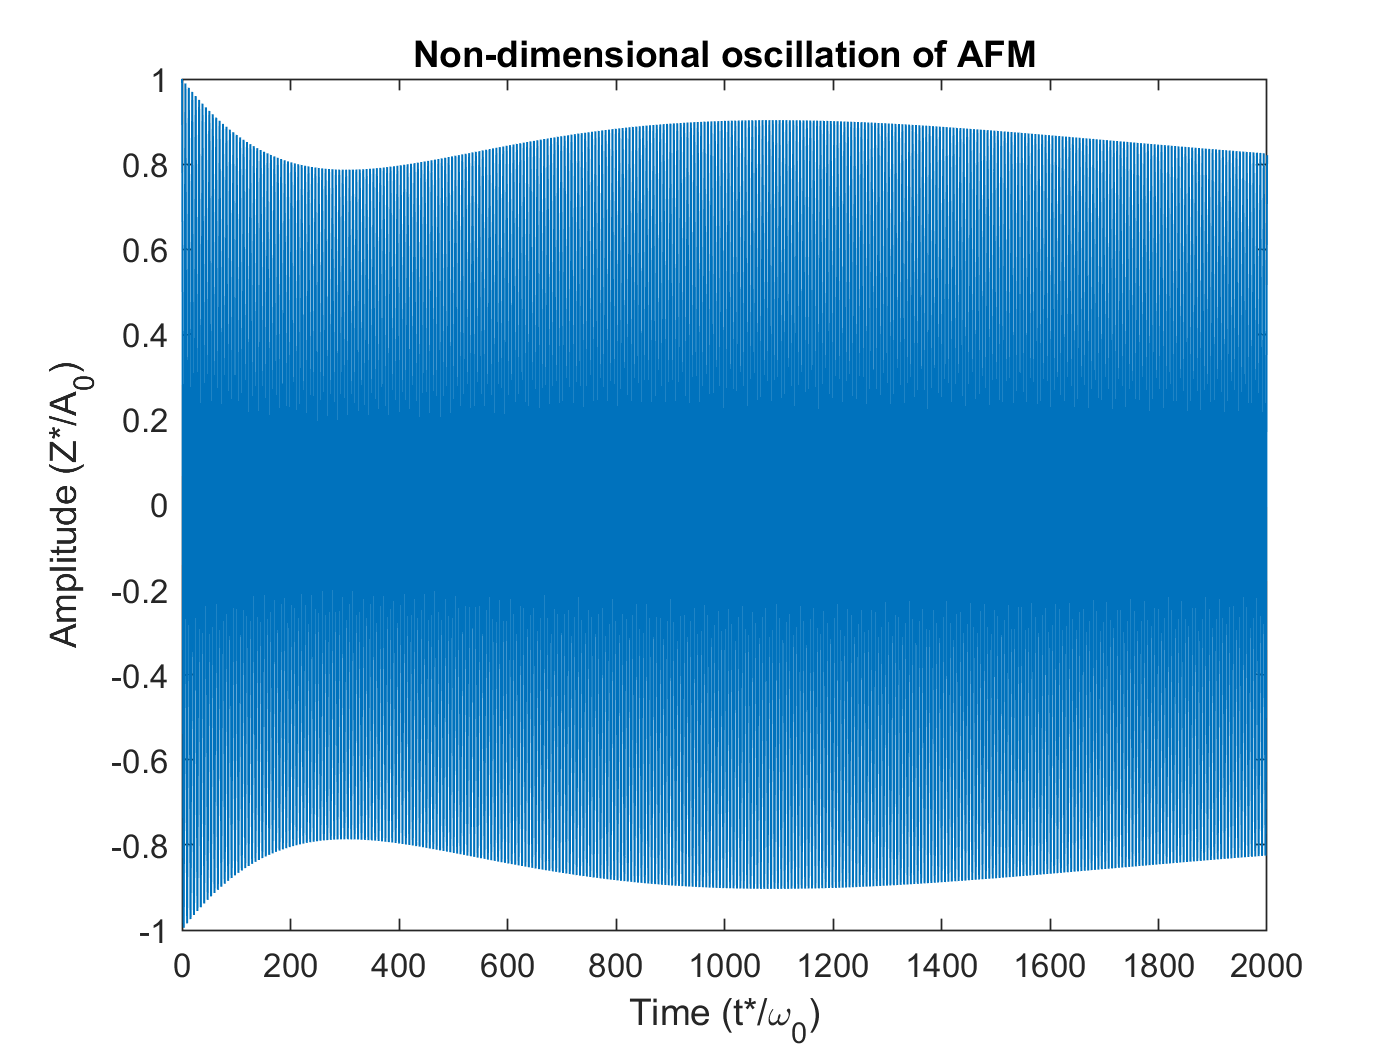

% --Plot a non-dimensionalized plot
    figure()
    plot(t,z)
        xlabel('Time (t*/\omega_0)')
        ylabel('Amplitude (Z*/A_0)')
        title('Non-dimensional oscillation of AFM')
        xlim([0 2000])

## Functions

    This section will be used for defining the functions that will be used to simulate the AFM of the system.

function [frequency, sol_amplitude, sol_phase] = fourier(signal,T)

    % --Format problem
            N = length(signal);                     % Number of datapoints
            sol_amplitude = [];                     % Solution vector
            sol_phase = [];
            n = 0:N - 1;                            % Temporal index   
            
    % --Calculate the DFT of the raw cosine signal
        for m = 0:N-1              % Frequency index
            
            % --First exponent term
                term_1 = (exp((-1i*2*pi*m*n)/N))';
                
            % --Complete Cm calculation
                C = sum(signal * term_1);
                
            % --Calculate magnitude
                Cm = 2*abs(C)/(N);
                phase = atand(C);
            
            % --Save values
                sol_amplitude = [sol_amplitude, Cm];
                sol_phase = [sol_phase phase];
                
        end
        
    % --Define Frequency
        frequency = (1/T)*(0:(N - 1));

end

function [value, isterminal, direction] = intermolecular_distance(~,zv)
    %{
        This is the event detection function that is used to calculate when
        we have hit the intermolecular distance. The three outputs are as
        follows: 
                value: when this is equal to zero, then the detection will
                       be switched, for our case that will be at d = a0
                isterminal: When zero is reached end integration, this will
                            be off
                direction: This specifies the directionality of the event,
                           since it switches both as the cantilever
                           increases in position and decreases it will be
                           set to both directions
    %}

    % --A0 and a0
        A0 = 2.0*10^-8;
        a0 = 1.6433*10^-10;
        Zc = 0.4;
        
    % --Setup 
        d = zv(1) + Zc - (a0/A0);
        value = d;                      % When this is 0, switching occurs
        isterminal = 0;                 % End Integration == False
        direction = 0;                  % Directions == both directions

end
